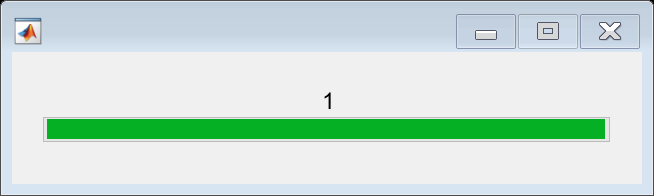

chromosome_of_interest = 'chr2';
TF_pos_filename = strcat('factor_pos_separated/', chromosome_of_interest, '_TF_pos.txt');
TFbinding_sites_file = fopen(TF_pos_filename,'rt');

mapObj_TF = containers.Map({'initiate'}, {0});
mapRegions = containers.Map({'initiate'}, {0});

TFbinding_sites_file = fopen('factorbookMotifPos.txt','rt');

f = waitbar(0, 'Please wait...');
thisline1 = fgetl(TFbinding_sites_file);
for i = 1:1000
    r = i/1000;
    progress = round(r,2);
    waitbar(progress,f,string(progress));
    if ~ischar(thisline1); break; end  %end of file

    C = strsplit(thisline1,"\t");

    chromosome = C(1,2);

    strand = C(1,7);
    
    if string(chromosome{1}) ~= 'chr1'
        break;
    end
 
    
    start = C(1,3);
    stop = C(1,4);
    name = C(1,5);
    name = name{1};


    start = str2double(start{1});
    stop = str2double(stop{1});
    
    if mapObj_TF.isKey(name)
        mapObj_TF(name) = mapObj_TF(name) + 1;
    else
        mapObj_TF(name) = 1;
    end

    thisline1 = fgetl(TFbinding_sites_file);
end

TFnames = keys(mapObj_TF)

TFnames = 1×84 cell array
    {'AP1'}    {'AP2'}    {'BARHL2'}    {'BHLHE40'}    {'CEBPB'}    {'CREB'}    {'CREB-ext'}    {'CTCF'}    {'CTCF-ext'}    {'E2F1'}    {'E2F4'}    {'EBF1'}    {'EGR1'}    {'ELF'}    {'ELF1'}    {'ESR1'}    {'ETS1'}    {'FOXA'}    {'GABP'}    {'GATA1'}    {'GATA1-ext'}    {'GATA3'}    {'HNF4'}    {'MAX'}    {'MEF2'}    {'MYC'}    {'NFE2'}    {'NFIC'}    {'NFKB1'}    {'NFY'}    {'NR2C2'}    {'NR3C1'}    {'NRF1'}    {'PAX5'}    {'POU2F2'}    {'PRDM1'}    {'PU1'}    {'REST'}    {'RFX5'}    {'RUNX1'}    {'RXRA'}    {'SP1'}    {'STAT1'}    {'TAL1'}    {'TCF12'}    {'TCF3'}    {'TCF7L2'}    {'TEAD4'}    {'UA1'}    {'UA2'}    {'UA3'}    {'UA6'}    {'UA7'}    {'UA9'}    {'UAK17'}    {'UAK18'}    {'UAK21'}    {'UAK22'}    {'UAK25'}    {'UAK26'}    {'UAK27'}    {'UAK29'}    {'UAK30'}    {'UAK31'}    {'UAK35'}    {'UAK36'}    {'UAK40'}    {'UAK41'}    {'UAK42'}    {'UAK45'}    {'UAK48'}    {'UAK52'}    {'UAK57'}    {'UAK61'}    {'USF'}    {'YY1'}    {'ZEB1'}    {'ZNF143'


for x = 1:length(TFnames)
    name = cell2mat(TFnames(x))
    mapObj_TF(name)
end

name = 'AP1'

ans = 11

name = 'AP2'

ans = 10

name = 'BARHL2'

ans = 1

name = 'BHLHE40'

ans = 13

name = 'CEBPB'

ans = 5

name = 'CREB'

ans = 5

name = 'CREB-ext'

ans = 9

name = 'CTCF'

ans = 104

name = 'CTCF-ext'

ans = 13

name = 'E2F1'

ans = 15

name = 'E2F4'

ans = 76

name = 'EBF1'

ans = 14

name = 'EGR1'

ans = 86

name = 'ELF'

ans = 2

name = 'ELF1'

ans = 15

name = 'ESR1'

ans = 4

name = 'ETS1'

ans = 1

name = 'FOXA'

ans = 4

name = 'GABP'

ans = 11

name = 'GATA1'

ans = 1

name = 'GATA1-ext'

ans = 1

name = 'GATA3'

ans = 2

name = 'HNF4'

ans = 5

name = 'MAX'

ans = 15

name = 'MEF2'

ans = 3

name = 'MYC'

ans = 22

name = 'NFE2'

ans = 3

name = 'NFIC'

ans = 1

name = 'NFKB1'

ans = 7

name = 'NFY'

ans = 3

name = 'NR2C2'

ans = 2

name = 'NR3C1'

ans = 1

name = 'NRF1'

ans = 43

name = 'PAX5'

ans = 10

name = 'POU2F2'

ans = 1

name = 'PRDM1'

ans = 1

name = 'PU1'

ans = 1

name = 'REST'

ans = 2

name = 'RFX5'

ans = 4

name = 'RUNX1'

ans = 6

name = 'RXRA'

ans = 2

name = 'SP1'

ans = 51

name = 'STAT1'

ans = 2

name = 'TAL1'

ans = 2

name = 'TCF12'

ans = 3

name = 'TCF3'

ans = 5

name = 'TCF7L2'

ans = 2

name = 'TEAD4'

ans = 2

name = 'UA1'

ans = 10

name = 'UA2'

ans = 5

name = 'UA3'

ans = 40

name = 'UA6'

ans = 1

name = 'UA7'

ans = 1

name = 'UA9'

ans = 5

name = 'UAK17'

ans = 16

name = 'UAK18'

ans = 14

name = 'UAK21'

ans = 2

name = 'UAK22'

ans = 4

name = 'UAK25'

ans = 14

name = 'UAK26'

ans = 9

name = 'UAK27'

ans = 9

name = 'UAK29'

ans = 6

name = 'UAK30'

ans = 4

name = 'UAK31'

ans = 3

name = 'UAK35'

ans = 2

name = 'UAK36'

ans = 2

name = 'UAK40'

ans = 1

name = 'UAK41'

ans = 1

name = 'UAK42'

ans = 89

name = 'UAK45'

ans = 2

name = 'UAK48'

ans = 2

name = 'UAK52'

ans = 4

name = 'UAK57'

ans = 5

name = 'UAK61'

ans = 8

name = 'USF'

ans = 15

name = 'YY1'

ans = 13

name = 'ZEB1'

ans = 3

name = 'ZNF143'

ans = 6

name = 'ZNF143-ext'

ans = 5

name = 'ZNF263'

ans = 69

name = 'ZNF281'

ans = 12

name = 'initiate'

ans = 0

name = 'v-JUN'

ans = 11

name = 'v-Maf'

ans = 5

mapObj_TF(TF_of_interest)

ans = 104

regions = keys(mapRegions)

regions = 1×1 cell array
    {'initiate'}


% for x = 1:length(regions)
%     name = cell2mat(regions(x))
%     mapRegions(name)
% end
fclose(TFbinding_sites_file);